Titanic_table = readtable('train.csv');
Titanic_data = (table2cell(Titanic_table));
head(Titanic_table)

class = cell2mat(Titanic_data(:,3));
Gender = Titanic_data(:,5);
PassengerId = cell2mat(Titanic_data(:,1));
Age = cell2mat(Titanic_data(:,6));
SibSP = cell2mat(Titanic_data(:,7));
Parch = cell2mat(Titanic_data(:,8));
survived = cell2mat(Titanic_data(:,2));
Fare = cell2mat(Titanic_data(:,10));

disp(grpstats(Titanic_table(:,{'Survived','Sex'}), 'Sex'))

                 Sex        GroupCount    mean_Survived
              __________    __________    _____________

    male      {'male'  }       577           0.18891   
    female    {'female'}       314           0.74204   



Feature engineering and data visualization section

Feature engineering

%Feature engineering 
%Replacing Nan values in age by mean age value
mean_age = mean(Age,'omitnan');
%disp(mean_age)
Age(isnan(Age))= mean_age;
% Discretize age to bins
Age_Category= discretize(Age, [0 15 30 65 85],'categorical',{'Under 15', '15-30', '30-65', 'Above 65'});
Age_Category = grp2idx(Age_Category);
%disp(Age_Category)

Data visualization:

%Age bar chart 
h = histogram(Age)

h =   Histogram with properties:

             Data: [891×1 double]
           Values: [40 22 16 86 114 283 95 72 48 41 32 16 15 4 6 1]
          NumBins: 16
         BinEdges: [0 5 10 15 20 25 30 35 40 45 50 55 60 65 70 75 80]
         BinWidth: 5
        BinLimits: [0 80]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


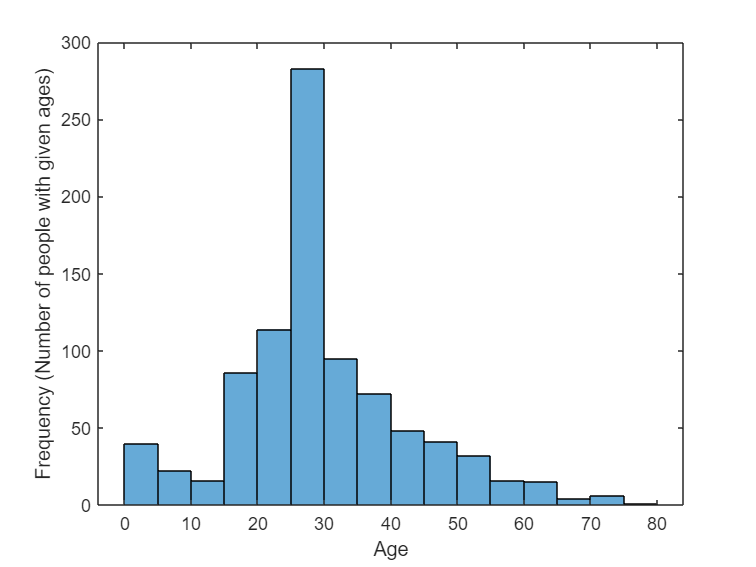

ylabel("Frequency (Number of people with given ages)")
xlabel("Age")

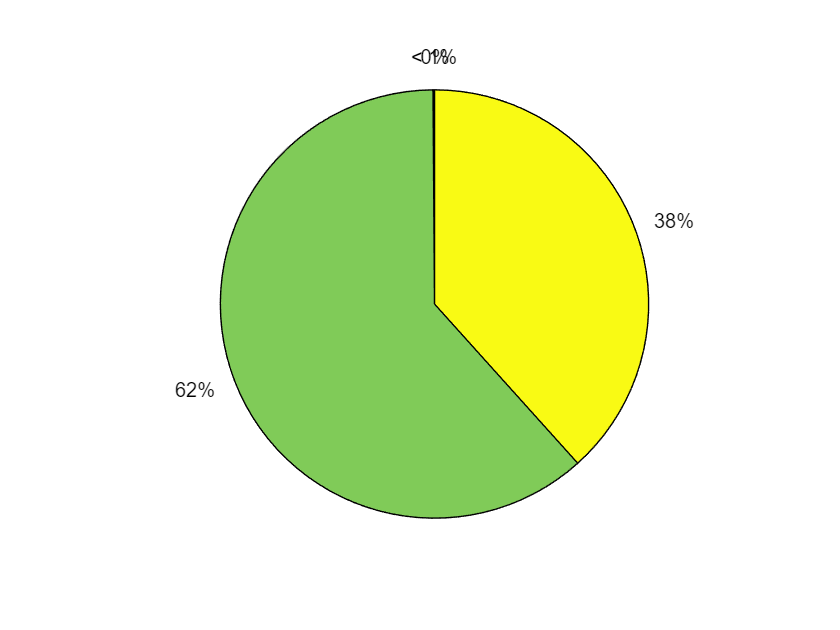

%pie chart for survived data
[C,ia,ic] = unique(survived);
a_counts = accumarray(ic,1);
value_counts = [C, a_counts];
pie(value_counts)

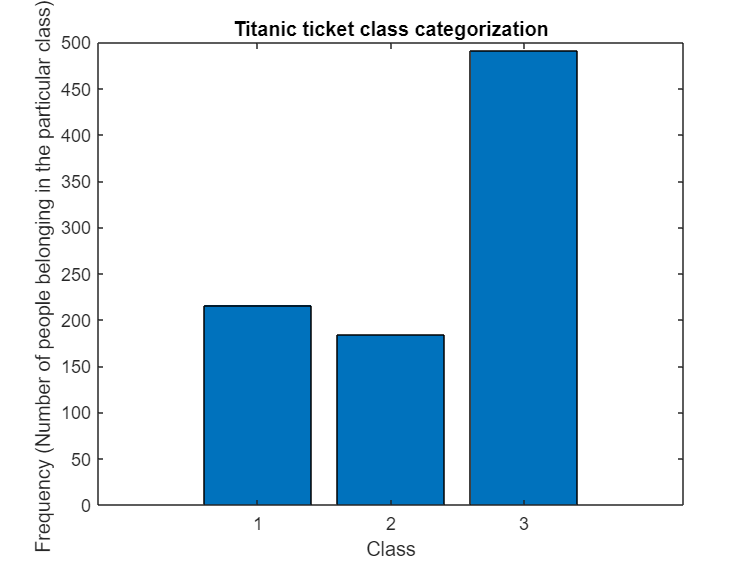

% for plotting ticket class categorization
A_1 = categorical(class);
categories(A_1);
X = countcats(A_1);
bar(X)
xlabel("Class")
ylabel("Frequency (Number of people belonging in the particular class) ")
title("Titanic ticket class categorization")

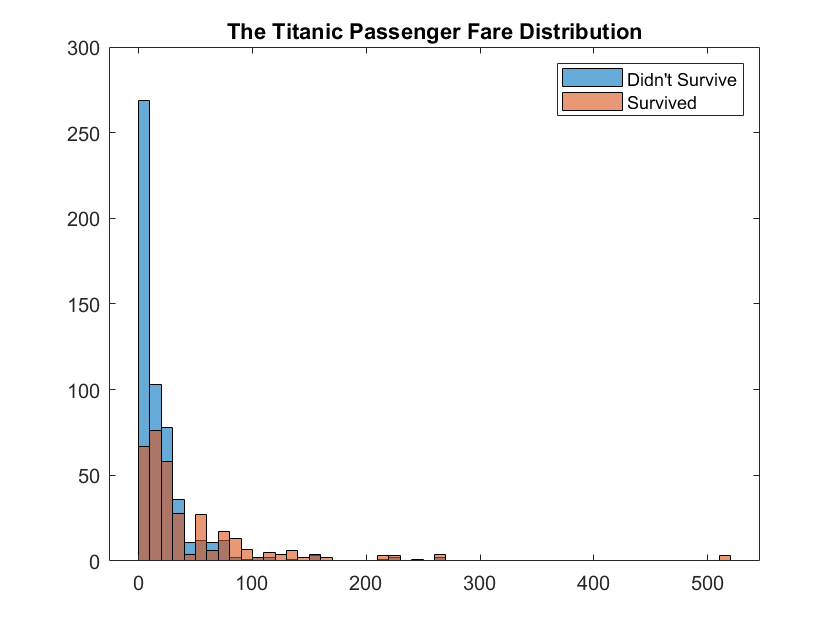

figure
histogram(Fare(survived == 0));         % fare histogram of non-survivers
hold on
histogram(Fare(survived == 1),0:10:520) % fare histogram of survivers
hold off
legend('Didn''t Survive', 'Survived')
title('The Titanic Passenger Fare Distribution')

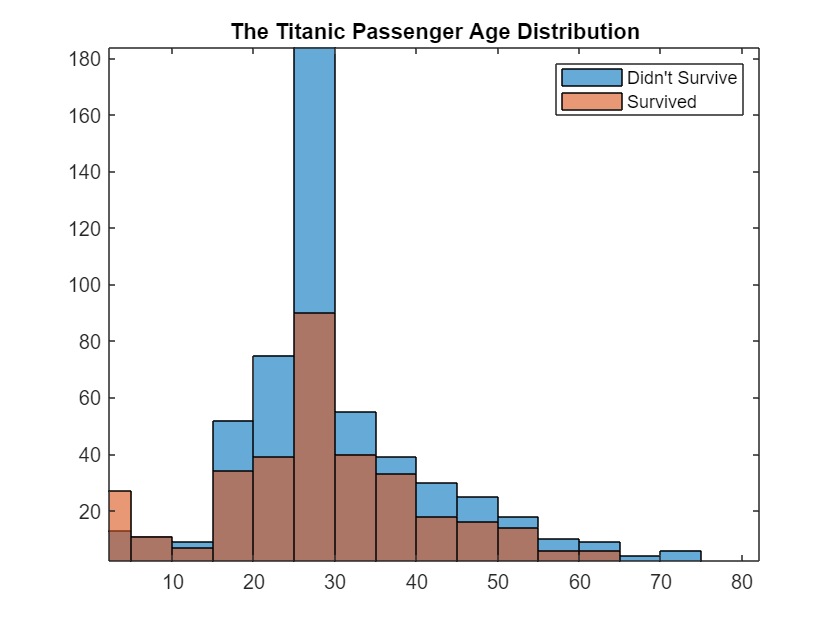


figure
histogram(Age(survived == 0))   % age histogram of non-survivers
hold on
histogram(Age(survived == 1))   % age histogram of survivers
hold off
legend('Didn''t Survive', 'Survived')
title('The Titanic Passenger Age Distribution')

Gender = grp2idx(Gender);
tbl = table(class,Gender, Age_Category, survived);

Machine learning algorithms being applied to the data 

Logistic Regression

% Fit a Logistic Regression Classifier, predict and find Accuracy using Confusion Matrix
log_model = fitglm(tbl, 'Distribution','binomial');
ypred = predict(log_model,tbl(:,1:end-1));
ypred = round(ypred); % to round the probabilities to 0 and 1 i.e.0:not survived, 1:survived
Confusion_Matrix = confusionmat(survived,ypred);
Accuracy = trace(Confusion_Matrix)/sum(Confusion_Matrix, 'all')

Accuracy = 0.7868

disp(Confusion_Matrix)

   458    91
    99   243



By using Decision Tree 

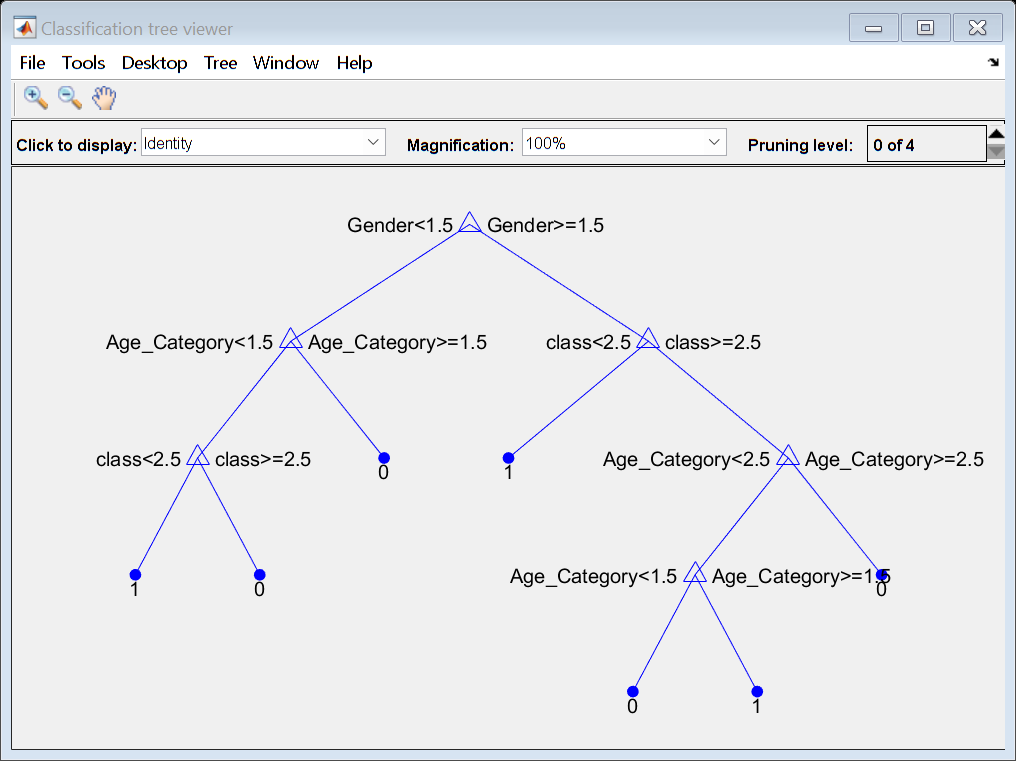

% Fit a decision tree and view it
mytree = fitctree(tbl(:,1:3),tbl(:,4));
view(mytree, 'Mode', 'graph');

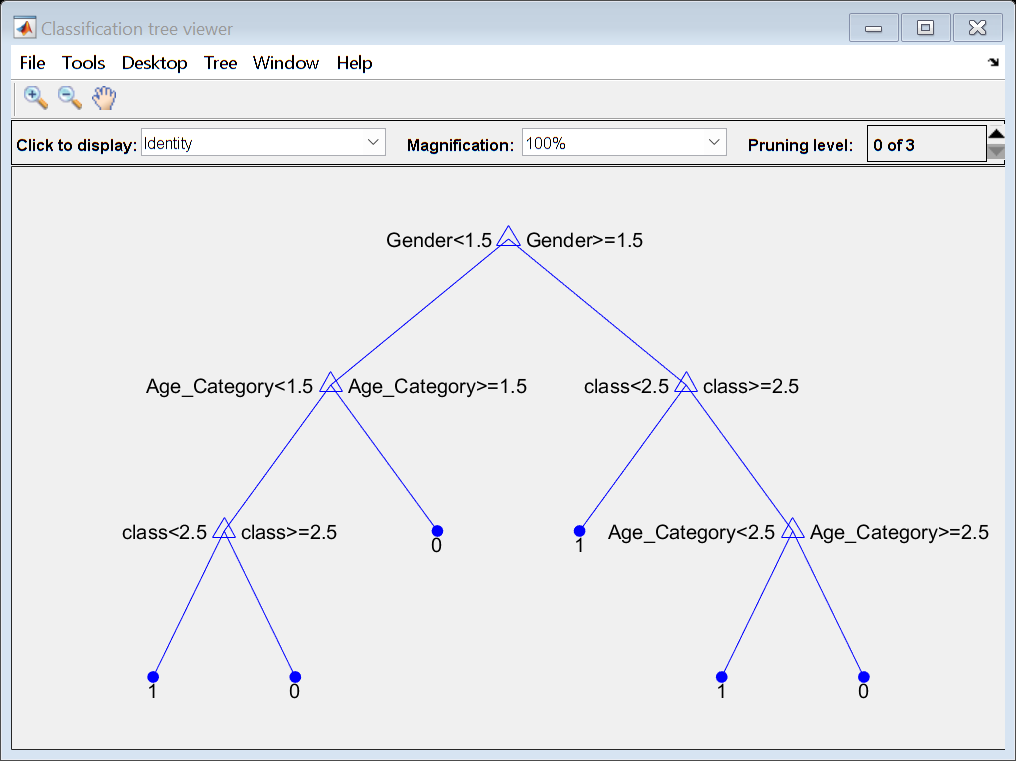


% Finding Best level for pruning using Misclassification error and cross-validation error. Pruning the Tree using the BestLevel
[~,~,~,BestLevel] = cvloss(mytree,'subtrees','all','treesize','min');
prunetree = prune(mytree,'Level',BestLevel);
view(prunetree,'mode','graph');


% Find Accuracy
label = predict(prunetree,tbl(:,1:end-1));
Confusion_Matrix_Tree = confusionmat(survived,label);
Accuracy_Tree = trace(Confusion_Matrix_Tree)/sum(Confusion_Matrix_Tree, 'all');

Making predictions with test data

Titanic_table_test = readtable('test.csv');
Titanic_data_test = (table2cell(Titanic_table_test));
head(Titanic_table_test)

ans = 8×11 table
    PassengerId    Pclass                          Name                             Sex        Age     SibSp    Parch      Ticket       Fare       Cabin       Embarked
    ___________    ______    ________________________________________________    __________    ____    _____    _____    __________    ______    __________    ________

        892          3       {'Kelly, Mr. James'                            }    {'male'  }    34.5      0        0      3.3091e+05    7.8292    {0×0 char}     {'Q'}  
        893          3       {'Wilkes, Mrs. James (Ellen Needs)'            }    {'female'}      47     

class = cell2mat(Titanic_data_test(:,2));
PassengerId = cell2mat(Titanic_data_test(:,1)); 
Gender = Titanic_data_test(:,4);
Age = cell2mat(Titanic_data_test(:,5));
SibSP = cell2mat(Titanic_data_test(:,6));
Parch = cell2mat(Titanic_data_test(:,7));

%Feature engineering 
%Replacing Nan values in age by mean age value
mean_age = mean(Age,'omitnan');
%disp(mean_age)
Age(isnan(Age))= mean_age;

% Discretize age to bins
Age_Category= discretize(Age, [0 15 30 65 85],'categorical',{'Under 15', '15-30', '30-65', 'Above 65'});
Age_Category = grp2idx(Age_Category);
%disp(Age_Category)

Gender = grp2idx(Gender);
tbl_test = table(class,Gender, Age_Category);
% Using Decision Tree 
ypred_tree = predict(prunetree,tbl_test(:,1:end));
generate_csv(PassengerId,ypred_tree)

function generate_csv(PassengerId, predicted_labels)
% to round the probabilities to 0 and 1 i.e.0:not survived, 1:survived
Survived = round(predicted_labels);
out = table(PassengerId, Survived);
writetable(out,'predictions.csv')
end
%Using Logistic Regression Model
%ypred_ = predict(log_model,tbl_test(:,1:end));
%writematrix(ypred_tree,'Predict_Logistic_model.csv')
